## **Exercise 5a (Modal Truncation)**

### **Task:**

- Decompose the full 8-compartment model into its modal components.

- Retain the modes that change slowly (slow dynamics) and ignore the fast ones.

### **Questions:**

- What assumptions are you making?

- Can you apply this method if you only have input/output data (without internal state information)?

- Is the reduced model stable (i.e., does it behave well over time)?

- How does the error (difference from the full model) look when you plot it over different frequencies?

- Why is the error exactly zero at ω=0?

### Answers: 

In model truncation, we assume the system does not change over time (its equations stay the same) and behaves in a linear way (outputs are directly proportional to inputs). We also assume that there is a noticeable difference between the slow and fast modes. In other words, the slow modes have eigenvalues with much smaller (in absolute value) real parts compared to the fast modes. Moreover, this method assumes that we have access to the full state–space model. That means we know the internal state variables and the system matrix A, not just the input and output. We also assume this matrix A, is diagonalizable, otherwise we can't extract the eigenvalues(modes).

We cannot apply this method directly using input/output data because Modal truncation relies on knowing the internal structure (the state variables) of the model to compute its eigenvalues and eigenvectors.

If we have only input/output data, we don’t have access to the internal modes or the state–space matrices. In that case, we would need to use other methods (like system identification) to first reconstruct a state–space model before we can perform modal truncation.

Regarding the stability, it means that, over time, the system settles down rather than growing without bound. If the full model is stable (all eigenvalues have negative real parts), and we retain only the slow modes (which are part of the stable system), then the reduced model is also stable. The reason is we are only removing fast-decaying modes, which are not essential for the long-term behavior.

To observe and compare the reduced model vs the original model, we plot their frequency response overtime, This error is the difference between the full model’s response $G(j\omega)$ and the reduced model’s response $G_{\text{reduced}}(j\omega)$

Based on this plot we observe that at low frequencies, the error is very small or even zero because the slow modes (which we kept) dominate the behavior. At high frequencies: The error increases because the fast modes (which were truncated) contribute more to the behavior at high frequencies. Their absence causes a difference in the high-frequency response.

At ω=0, we’re looking at the system’s behavior for a constant input (which is called static gain, in other words it's how much the system "amplifies" or "scales" a constant input) Both the full model and the reduced model are designed to have the same static gain, which means they produce the same output for a constant input. Therefore, the difference (error) is exactly zero at zero frequency.

### Code:

clc;clear;close all;

% Define the full 8-compartment system.
% (This is based on the lecture notes for the compartmental model.)
A = [-10.5,  0.5,    0,     0,    0,    0,    0,    5;
      10.5, -11,    0.5,   0,    0,    0,    0,    0;
         0,  10.5,  -11,    0.5,  0,    0,    0,    0;
         0,     0,  10.5, -10.5,  0,    0,    0,    0;
         0,     0,    0,    20,  -20,   0,    0,    0;
         0,     0,    0,     0,   20, -20,    0,    0;
         0,     0,    0,     0,    0,   20, -20,    0;
         0,     0,    0,     0,    0,    0,   20,  -20];
B = [5; 0; 0; 0; 0; 0; 0; 0];
C = [0 0 0 1 0 0 0 0];  % Output is taken from compartment 4.
D = 0;

% Create the full state-space system
sys_full = ss(A, B, C, D);

%% Compute eigenvalues and eigenvectors of A.
% The eigenvalues represent the different dynamic modes of the system.
[eigVec, eigValMat] = eig(A);
eigValues = diag(eigValMat);

fprintf('Eigenvalues of the full system:\n');

Eigenvalues of the full system:


disp(eigValues);

  -1.0977 + 0.0000i
  -5.3616 + 8.5553i
  -5.3616 - 8.5553i
 -15.4767 +12.2506i
 -15.4767 -12.2506i
 -29.4422 + 0.0000i
 -25.3917 + 8.7618i
 -25.3917 - 8.7618i



%% Identify slow and fast modes.
% Slow modes have eigenvalues with smaller magnitude of the real part.
% Here, we choose a threshold for real part of eignevalues; 

threshold = 5;  
slowModeIdx = find(abs(real(eigValues)) < threshold);
fastModeIdx = find(abs(real(eigValues)) >= threshold);

disp('Indices of slow modes:');

Indices of slow modes:


disp(slowModeIdx);

     1



disp('Indices of fast modes:');

Indices of fast modes:


disp(fastModeIdx);

     2
     3
     4
     5
     6
     7
     8



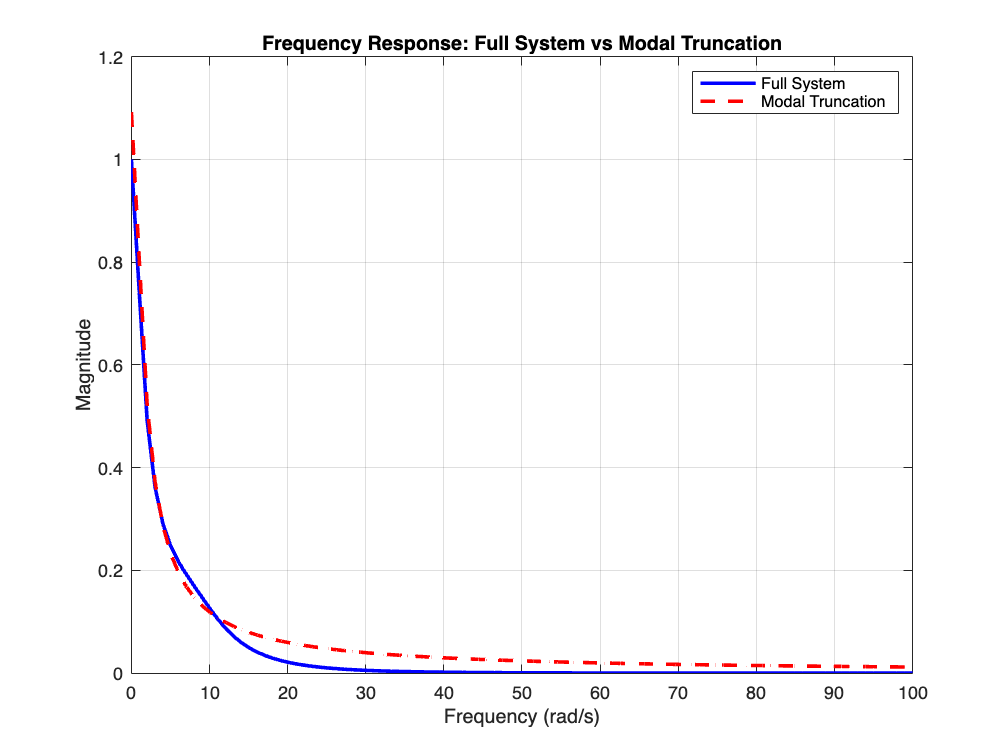


%% Construct the Modal Transformation.
% Assuming A is diagonalizable.
% The transformation matrix T is formed by the eigenvectors.
T = eigVec;          % T: full modal transformation
T_inv = inv(T);      % Inverse of T

% Transform the full system to modal coordinates:
A_modal = T_inv * A * T;
B_modal = T_inv * B;
C_modal = C * T;

% At this point, A_modal is nearly (or exactly) diagonal (or block-diagonal).

%% Modal Truncation - Retain Only Slow Modes.
% Extract the submatrices corresponding to the slow modes.
A_slow = A_modal(slowModeIdx, slowModeIdx);
B_slow = B_modal(slowModeIdx);
C_slow = C_modal(:, slowModeIdx);
D_slow = D;  % D remains unchanged

% Create the reduced-order system using only the slow modes.
sys_modal = ss(A_slow, B_slow, C_slow, D_slow);

%% Compare the full and reduced systems.
% Define a frequency vector from 0 to 100 rad/s.
w = linspace(0, 100, 100);

% Compute the ABSOLUTE frequency response (magnitude) for each system.
G_full  = squeeze(abs(freqresp(sys_full, w)));
G_modal = squeeze(abs(freqresp(sys_modal, w)));

% Compute the error between the full and reduced model.
error_modal = G_full - G_modal;

%% Plotting the Frequency Responses and the Error.

% Frequency response of the full system vs. modal truncated model.
figure;
plot(w, G_full, 'b', 'LineWidth', 2); hold on;
plot(w, G_modal, 'r--', 'LineWidth', 2);
xlabel('Frequency (rad/s)');
ylabel('Magnitude');
legend('Full System', 'Modal Truncation');
title('Frequency Response: Full System vs Modal Truncation');
grid on;

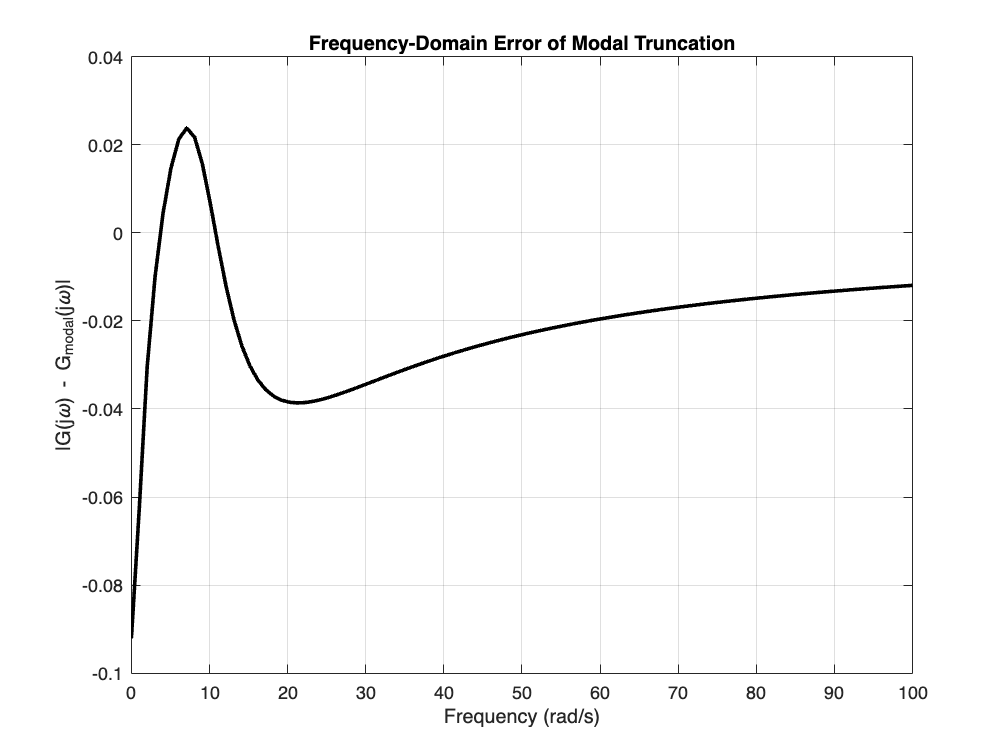


% Frequency-domain error between full system and modal truncated model.
figure;
plot(w, error_modal, 'k', 'LineWidth', 2);
xlabel('Frequency (rad/s)');
ylabel('|G(j\omega) - G_{modal}(j\omega)|');
title('Frequency-Domain Error of Modal Truncation');
grid on;

## **Exercise 5b (Time Moment Matching)**

### **Task:**

- Construct simple models (with orders 3, 4, and 5) using the time moment matching method.

### **Questions to Answer:**

- How do you choose the degrees of the numerator and denominator in your approximant?

- What assumptions does this method require?

- Can this method be used with experimental data?

- Are the approximations guaranteed to be stable?

- How do the impulse (time-domain) and frequency-domain errors compare?

- Why is the error zero (or nearly zero) for low frequencies?

### Answers:

For a strictly proper system (where the transfer function goes to zero as s→∞), we typically require m<n. According to answers obtained from online resources, a common choice is to set m=n−1 or m≤n so that the approximant does not introduce non-physical behavior like differentiators. This affects how many time moments (or derivatives at s=0) the approximant will match. More matched moments mean the low-frequency behavior (and early time impulse response) is captured very accurately.

Of course we want the system to be asymptotically stable (so that all the integrals defining the moments converge) and smooth (so that the Taylor series expansion about 𝑠 = 0 is valid). We also need the impulse response or, equivalently, the Taylor series of the transfer function at s=0.

If we can experimentally measure the impulse or step response, we can estimate the time moments (by integrating the response multiplied by time powers).

Even if the full system is stable, the approximant obtained through time moment matching is not guaranteed to be stable. The matching conditions do not enforce stability by themselves. After constructing the approximant, we will examine its poles (the roots of the denominator) to ensure that they all lie in the left half-plane (for continuous–time systems).

Because the approximant is designed to match a finite number of time moments, the impulse response of the approximant will closely match that of the full system for early times. Similarly, the low-frequency behavior (near s=0 or ω=0) will be nearly identical between the full and approximated systems. However, as we move away from s=0 (or as frequency increases), the approximant diverge from the true system.

Since the approximant is constructed to match the first few terms of the Taylor series expansion of the full system, it exactly replicates the behavior of the full system at very low frequencies (close to s=0), hence the error is zero (or near zero)

### Code:

% Compute the impulse response and time moments.
t_imp = linspace(0, 1, 1000);    % time vector for impulse response
impulse_full = squeeze(impulse(sys_full, t_imp));
t_imp = t_imp(:);  % force to column vector

% Number of moments: For an order 5 approximant with m=4, n=5, we need at
% least 10 moments. Note that in the function buildPadeApprox() we compute 
% time moments again, here we do this for demonstration.

numMoments = 10; 

moments = zeros(1, numMoments);
for k = 0:(numMoments-1)
    moments(k+1) = trapz(t_imp, impulse_full .* (t_imp.^k));
end

fprintf('Computed time moments: \n');

Computed time moments: 


disp(moments);

    0.6348    0.3028    0.1820    0.1265    0.0963    0.0777    0.0651    0.0561    0.0493    0.0439



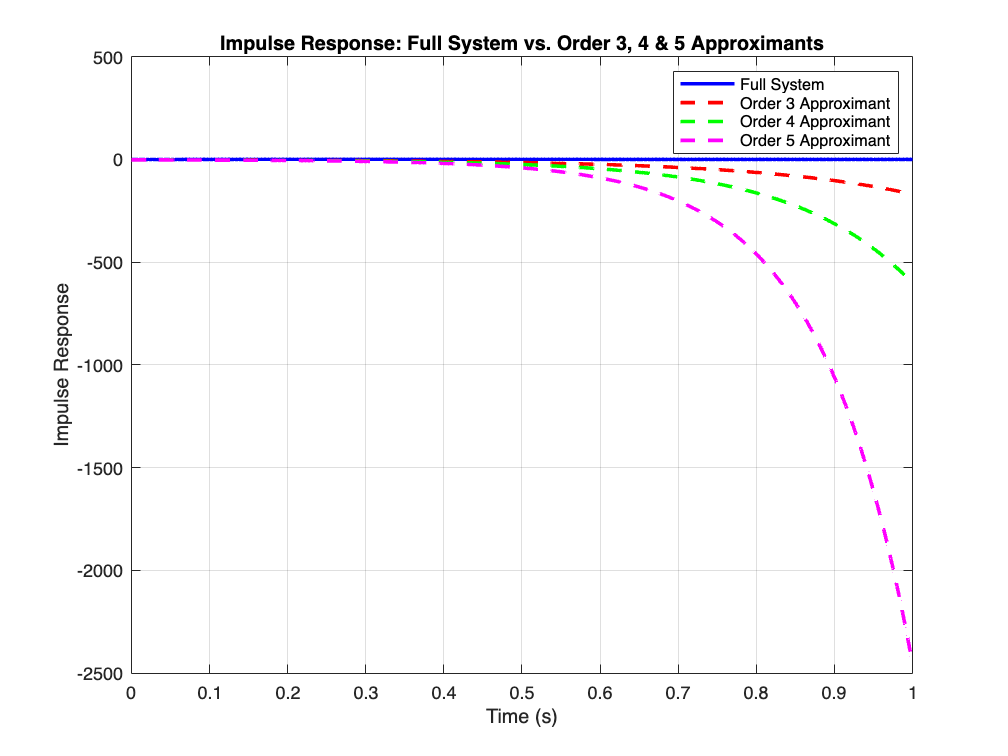


% Build the approximants:
sys_pade3 = buildPadeApprox(sys_full, 2, 3, t_imp);  % Order 3 approximant (m=2, n=3, needs 6 moments)
sys_pade4 = buildPadeApprox(sys_full, 3, 4, t_imp);  % Order 4 approximant (m=3, n=4, needs 8 moments)
sys_pade5 = buildPadeApprox(sys_full, 4, 5, t_imp);  % Order 5 approximant (m=4, n=5, needs 10 moments)

% Compute and plot the impulse responses.
figure;
[y_full, t_full] = impulse(sys_full, t_imp);
[y_pade3, t_pade3] = impulse(sys_pade3, t_imp);
[y_pade4, t_pade4] = impulse(sys_pade4, t_imp);
[y_pade5, t_pade5] = impulse(sys_pade5, t_imp);

plot(t_full, y_full, 'b', 'LineWidth', 2); hold on;
plot(t_pade3, y_pade3, 'r--', 'LineWidth', 2);
plot(t_pade4, y_pade4, 'g--', 'LineWidth', 2);
plot(t_pade5, y_pade5, 'm--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Impulse Response');
title('Impulse Response: Full System vs. Order 3, 4 & 5 Approximants');
legend('Full System', 'Order 3 Approximant', 'Order 4 Approximant', 'Order 5 Approximant');
grid on;

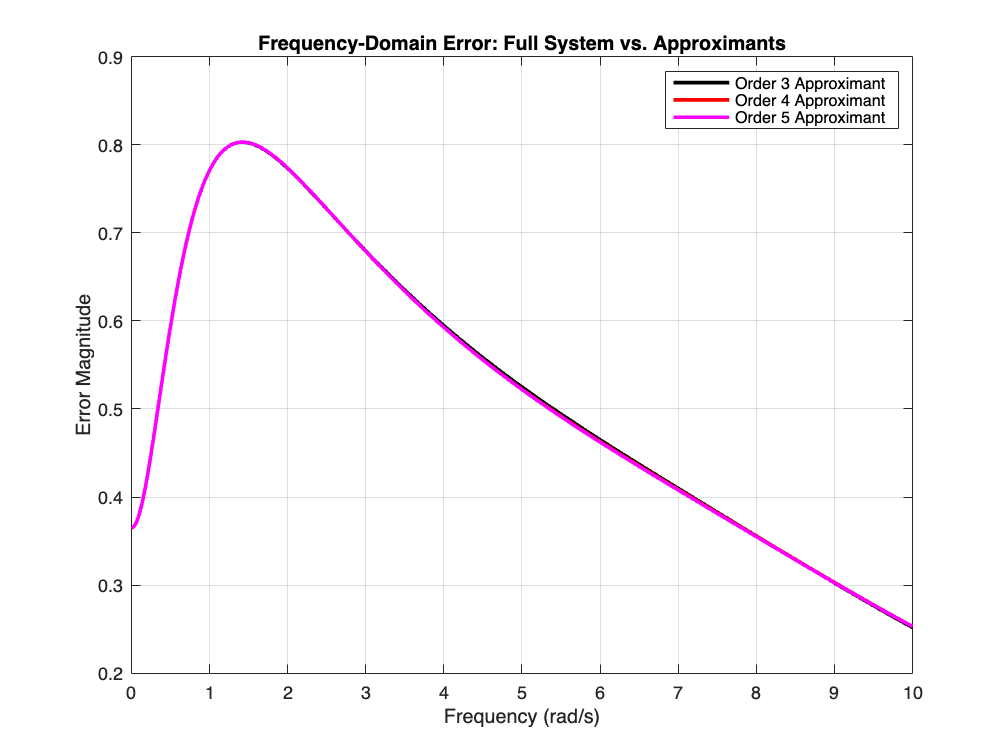


% Frequency domain comparison:
% We use a frequency vector that includes 0 from 0 to 10 rad/s.
w = linspace(0, 10, 1000);
G_full   = squeeze(freqresp(sys_full, w));
G_pade3  = squeeze(freqresp(sys_pade3, w));
G_pade4  = squeeze(freqresp(sys_pade4, w));
G_pade5  = squeeze(freqresp(sys_pade5, w));

% Compute error (magnitude difference) for each approximant.
error_freq3 = abs(G_full - G_pade3);
error_freq4 = abs(G_full - G_pade4);
error_freq5 = abs(G_full - G_pade5);

figure;
plot(w, error_freq3, 'k', 'LineWidth', 2); hold on;
plot(w, error_freq4, 'r', 'LineWidth', 2);
plot(w, error_freq5, 'm', 'LineWidth', 2);
xlabel('Frequency (rad/s)');
ylabel('Error Magnitude');
title('Frequency-Domain Error: Full System vs. Approximants');
legend('Order 3 Approximant', 'Order 4 Approximant', 'Order 5 Approximant');
grid on;

## **Exercise 5c (Physics-Based Reduction)**

### **Task:**

- Replace the four smaller compartments on the right side with one single compartment (keeping the total volume constant).

### **Questions to Answer:**

- How does this aggregation affect the model?

- What assumptions are made (like assuming similar dynamics for the aggregated compartments)?

- Is the reduced model stable?

- What does the error look like in the frequency domain, and where is it zero?

- How does this compare to the other reduction methods?

### **Answers**

The original model has 8 compartments (states), and after aggregation, the reduced model has only 5 states. The fast dynamics among the four smaller compartments are combined into one aggregated state. This may smooth out or lose some detailed transient behavior but preserves the overall (steady-state) behavior if the total volume and flows are preserved.

It is assumed that the four smaller compartments have similar dynamic behavior. Their responses are assumed to be similar enough that summing them provides a good approximation. The method assumes that the dynamics are linear and that the interconnections allow for a simple summation of states without significantly altering the system’s overall response. The total volume of the aggregated compartments remains the same, which helps in preserving the static gain.

Becasue the full system is stable, then the reduced model is also stable. In our code, we use a projection that maintains the physical balance, so the reduced model should inherit the stability of the full model.

The frequency–domain error (the difference in magnitude of the transfer functions) is zero at ω=0 because the static gain is preserved by the aggregation. At higher frequencies, the error increases because the fast dynamics (the detailed interactions among the small compartments) are not captured exactly by the aggregated model.

This method uses physical insight (the structure of the compartments) rather than purely mathematical transformations. It is intuitive if we know the process structure. Modal truncation uses eigen-decomposition to keep only the dominant (slow) modes. It is mathematically systematic but requires state-space information and eigenvalue separation. Pade approximation or time moment matching focuses on matching the low-frequency (time moment) behavior of the system. It guarantees a good fit near ω=0 but may not capture high-frequency dynamics well.

### Code:

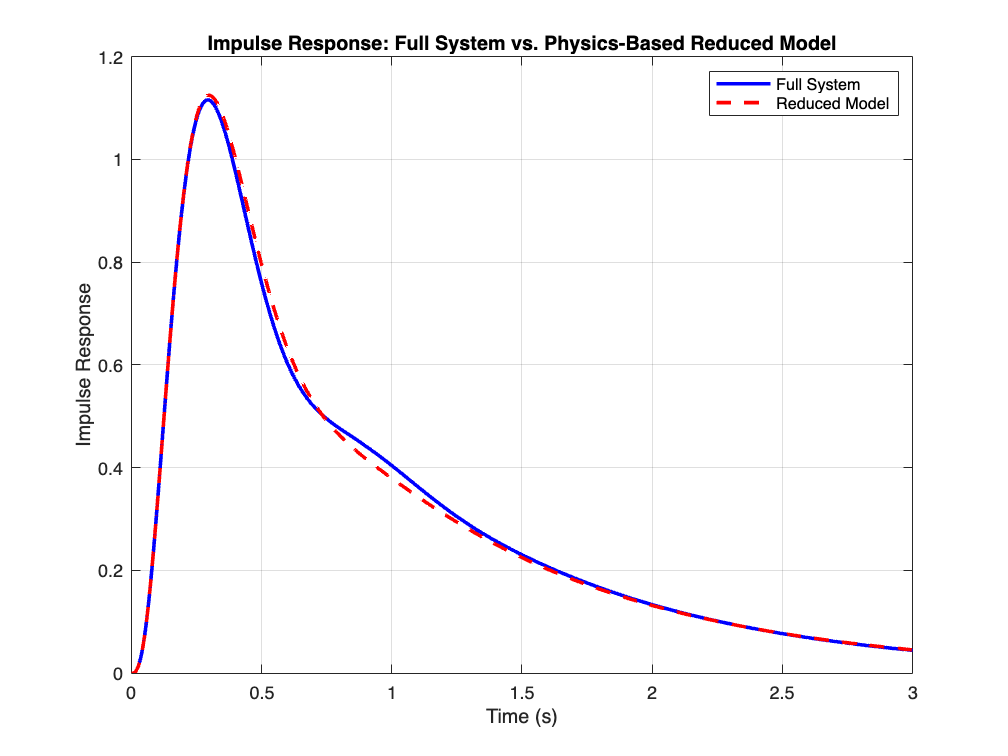

% Create a projection (aggregation) matrix P.
% We want to keep the first 4 compartments as is, and let the 5th state be the sum of compartments 5 to 8.
P = [ eye(4), zeros(4,4);   % 4x8: keeps C1-C4
      zeros(1,4), ones(1,4)]; % 1x8: sums C5-C8

% Compute the pseudoinverse of P
P_pinv = pinv(P);

% Build the reduced-order system matrices.
A_red = P * A * P_pinv;
B_red = P * B;
C_red = C * P_pinv;
D_red = D;

sys_red = ss(A_red, B_red, C_red, D_red);

% Compare the full system and the reduced system.
% Plot impulse responses:
t_imp = linspace(0, 3, 1000);
[y_full, t_full] = impulse(sys_full, t_imp);
[y_red, t_red]   = impulse(sys_red, t_imp);

figure;
plot(t_full, y_full, 'b', 'LineWidth', 2); hold on;
plot(t_red, y_red, 'r--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Impulse Response');
title('Impulse Response: Full System vs. Physics-Based Reduced Model');
legend('Full System', 'Reduced Model');
grid on;

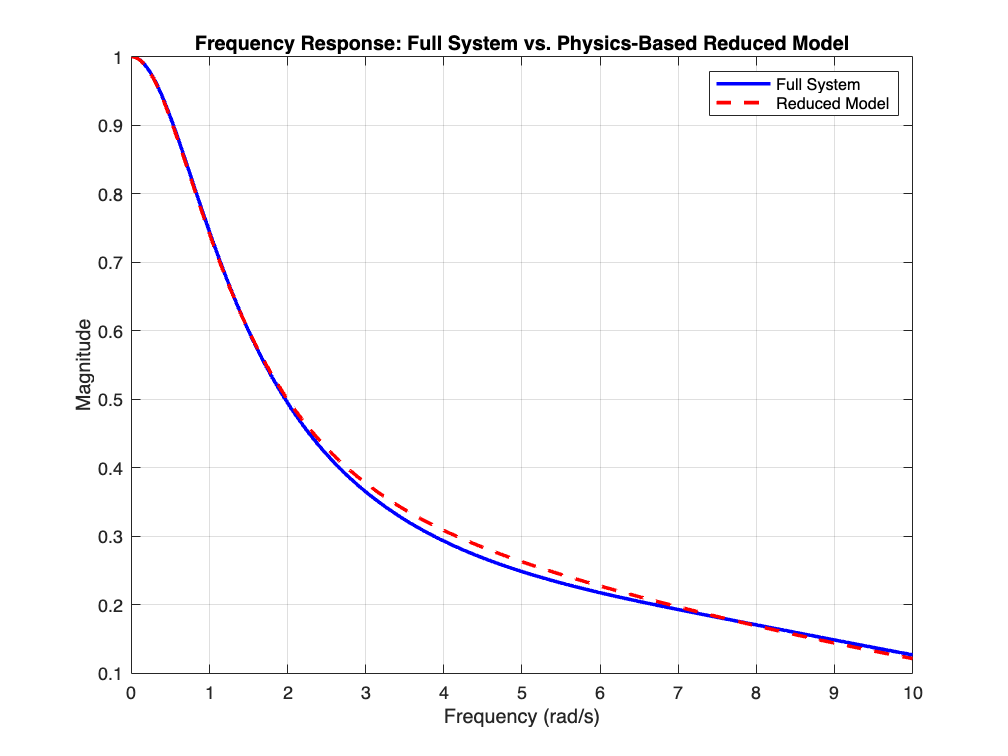


% Frequency domain comparison:
w = linspace(0, 10, 1000);
G_full = squeeze(freqresp(sys_full, w));
G_red  = squeeze(freqresp(sys_red, w));

figure;
plot(w, abs(G_full), 'b', 'LineWidth', 2); hold on;
plot(w, abs(G_red), 'r--', 'LineWidth', 2);
xlabel('Frequency (rad/s)');
ylabel('Magnitude');
title('Frequency Response: Full System vs. Physics-Based Reduced Model');
legend('Full System', 'Reduced Model');
grid on;

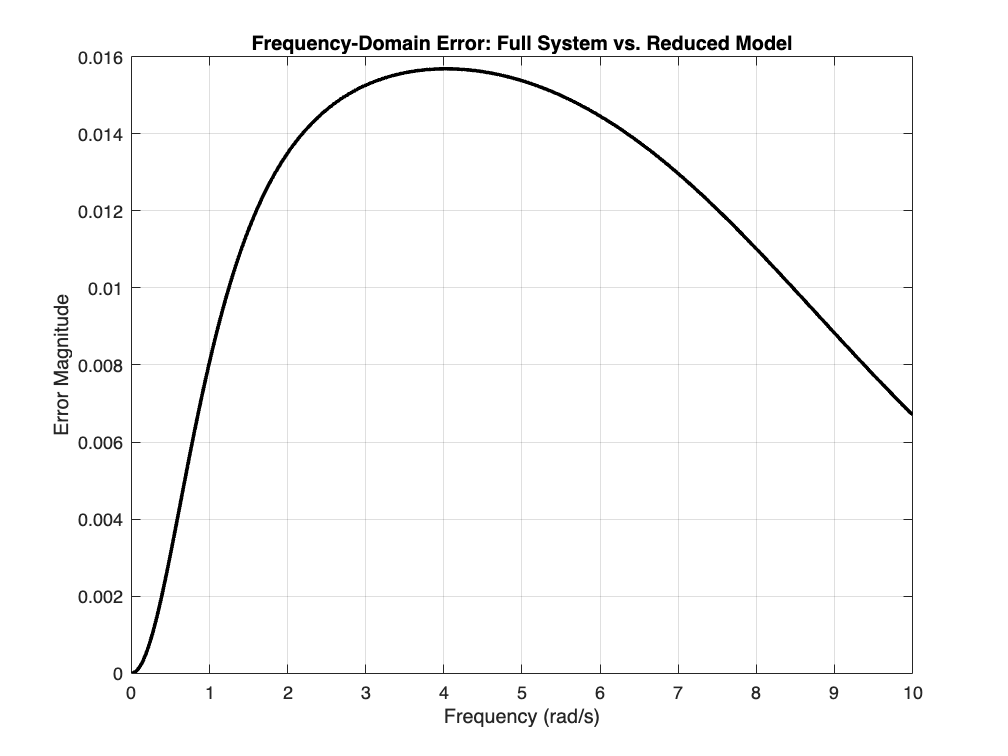


% Plot the error (difference) between the frequency responses.
error_freq = abs(G_full - G_red);
figure;
plot(w, error_freq, 'k', 'LineWidth', 2);
xlabel('Frequency (rad/s)');
ylabel('Error Magnitude');
title('Frequency-Domain Error: Full System vs. Reduced Model');
grid on;

## **Exercise 5d (Comparison)**

### **Task:**

- Compare the different approximations (modal truncation, time moment matching, and physics-based reduction).

### **Questions to Answer:**

- For which frequencies is the best fit required (usually low frequencies are most important)?

- Which method would you recommend, and why?

- Show the error plots (frequency response) for each method.

### Answers:

In many practical control and process applications, the system’s steady–state and slow dynamic behavior are crucial. These correspond to low frequencies (around ω=0). All methods are designed to match the DC gain so that the error is zero there. Time moment matching, in particular, guarantees an excellent fit at low frequencies because it directly matches the Taylor series (or time moments) of the full system.

If low-frequency accuracy is paramount and we have reliable impulse response data, we would lean toward **time moment matching** because it guarantees an exact fit (zero error) at ω=0 and excellent accuracy for low frequencies. However, if the physical structure is very clear and the compartments are naturally grouped, then **physics-based reduction** is also very effective.

### **Code:**

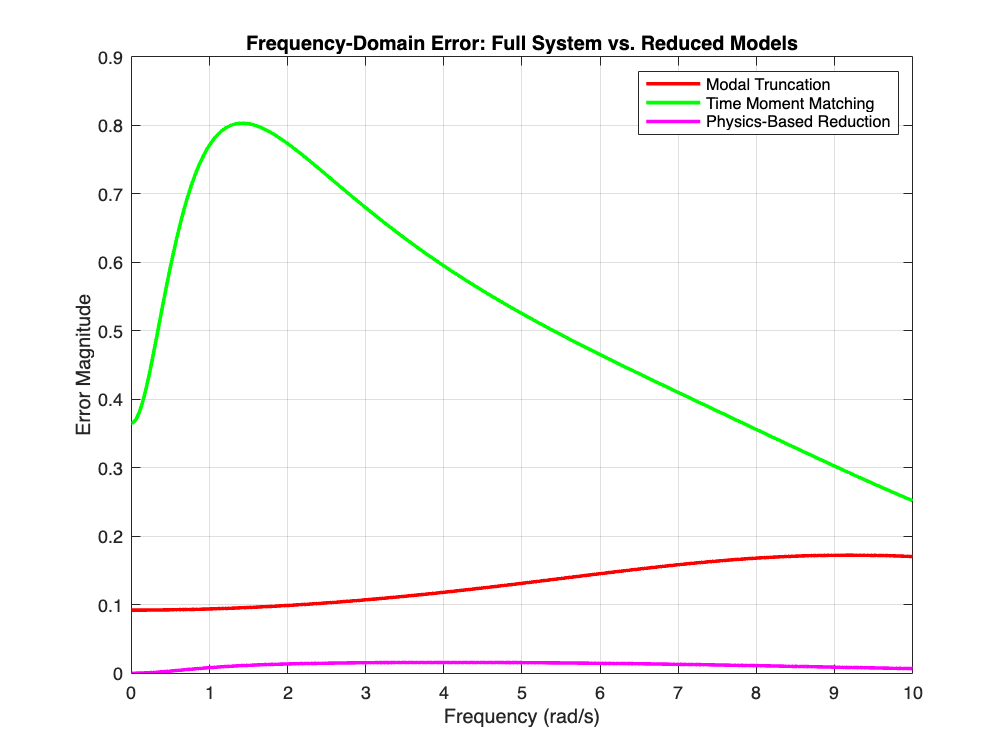

% Define a frequency vector that covers low and moderate frequencies.
w = linspace(0, 10, 1000);  % from DC (0 rad/s) to 10 rad/s

% Compute frequency responses (complex values) for each system.
G_full   = squeeze(freqresp(sys_full, w));
G_modal  = squeeze(freqresp(sys_modal, w));
G_pade3  = squeeze(freqresp(sys_pade3, w)); % using order 3 pade approx.
G_phys   = squeeze(freqresp(sys_red, w));   % physics-based reduced model

% Compute errors (magnitude difference) relative to the full system.
error_modal = abs(G_full - G_modal);
error_pade3 = abs(G_full - G_pade3);
error_phys  = abs(G_full - G_phys);

%% Plot Frequency-Domain Errors

figure;
plot(w, error_modal, 'r', 'LineWidth', 2); hold on;
plot(w, error_pade3, 'g', 'LineWidth', 2);
plot(w, error_phys,  'm', 'LineWidth', 2);
xlabel('Frequency (rad/s)');
ylabel('Error Magnitude');
title('Frequency-Domain Error: Full System vs. Reduced Models');
legend('Modal Truncation', 'Time Moment Matching', 'Physics-Based Reduction');
grid on;

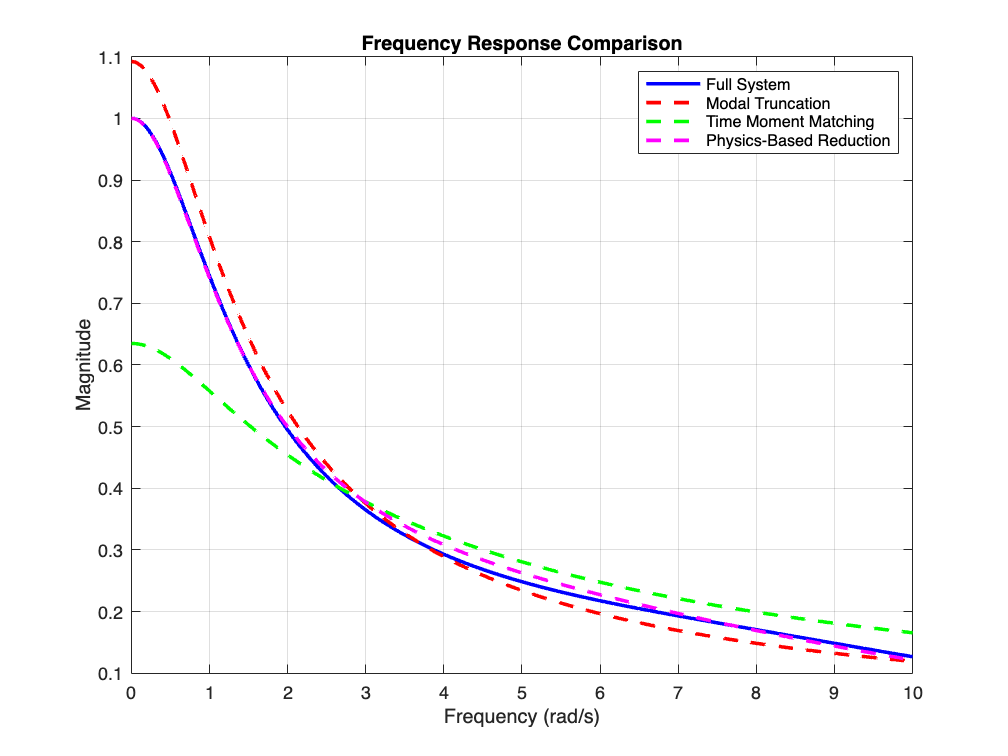


%% Plot Frequency Responses for Visual Comparison

figure;
plot(w, abs(G_full), 'b', 'LineWidth', 2); hold on;
plot(w, abs(G_modal), 'r--', 'LineWidth', 2);
plot(w, abs(G_pade3), 'g--', 'LineWidth', 2);
plot(w, abs(G_phys),  'm--', 'LineWidth', 2);
xlabel('Frequency (rad/s)');
ylabel('Magnitude');
title('Frequency Response Comparison');
legend('Full System', 'Modal Truncation', 'Time Moment Matching', 'Physics-Based Reduction');
grid on;

%% function to compute pade approx of a system (used in part 3)
function sys_approx = buildPadeApprox(sys, m, n, t_imp)

% Compute the impulse response of the system.
h = impulse(sys, t_imp);
h = squeeze(h);       % Ensure h is a vector.
t_imp = t_imp(:);     % Force t_imp to be a column vector.

% Compute time moments:
% m_k = ∫_0^∞ t^k * h(t) dt.
% We need at least m+n+1 moments (for k=0,...,m+n).
numMoments = m + n + 1;
moments = zeros(1, numMoments);
for k = 0:(numMoments-1)
    moments(k+1) = trapz(t_imp, h .* (t_imp.^k));
end

% Convert moments to a column vector.
k = moments(:);  % k(1)=k0, k(2)=k1, etc.

% Set up the linear system for denominator coefficients b1,...,b_n.
% For i = 1 to n (corresponding to orders m+1,...,m+n):
%   k(m+i) + b1*k(m+i-1) + ... + b_n*k(m+i-n) = 0.
A_lin = zeros(n, n);
rhs   = zeros(n, 1);
for i = 1:n
    for j = 1:n
        A_lin(i, j) = k(m + i - j + 1);  % k(m+i-j)
    end
    rhs(i) = -k(m + i + 1);  % -k(m+i)
end

% Solve for b1,...,b_n (use pseudoinverse for numerical robustness)
b_coeff = pinv(A_lin) * rhs;
b = [1; b_coeff];  % b0 is set to 1 
% (based on what I learned from chatGPT it's best practice)

% Compute numerator coefficients a0,...,a_m.
a = zeros(m+1, 1);
for i = 0:m
    s_val = k(i+1);  % This is k_i (MATLAB index i+1).
    for j = 1:min(i, n)
        s_val = s_val + b(j+1) * k(i - j + 1);
    end
    a(i+1) = s_val;
end

% Convert coefficients to MATLAB's standard polynomial format (descending powers)
num_coeff = fliplr(a.');
den_coeff = fliplr(b.');

% Create the transfer function approximant.
sys_approx = tf(num_coeff, den_coeff);
end